% splinecase.m
% matlab code for case 1

% elapsed time
%t=[0 3.1 10.3 30.1]; car='Honda';
%t=[0 3.2 12.0 38.2]; car='Jeep';
%t=[0 4.2 12.8 38.7]; car='Kia';
%t=[0 2.8 9.5 22.7]; car='Subaru';
t=[0 3.0 10.2 31.7]; car='Toyota';

t1=t(2)

t1 = 3

t2=t(3)-t(2)

t2 = 7.2000

t3=t(4)-t(3)

t3 = 21.5000

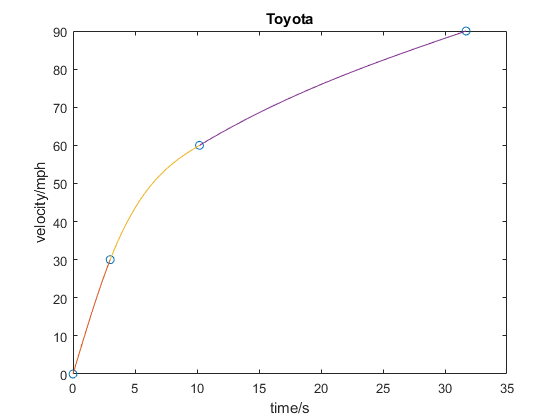


% create A matrix (12x12) and plug in the nonzero coefficients
A=[0 0 0 1           0 0 0 0            0 0 0 0;
   t1^3 t1^2 t1 1    0 0 0 0            0 0 0 0;
   0 0 0 0           0 0 0 1            0 0 0 0;
   0 0 0 0           t2^3 t2^2 t2 1     0 0 0 0;
   0 0 0 0           0 0 0 0            0 0 0 1;
   0 0 0 0           0 0 0 0            t3^3 t3^2 t3 1;
   3*t1^2 2*t1  1 0  0 0 -1 0           0 0 0 0;
   0 0 0 0           3*t2^2 2*t2 1 0    0 0 -1 0;
   6*t1 2 0 0        0 -2 0 0           0 0 0 0;
   0 0 0 0           6*t2 2 0 0         0 -2 0 0;
   0 2 0 0           0 0 0 0            0 0 0 0 ;
   0 0 0 0           0 0 0 0            6*t3 2 0 0];

% the B vector is the same for all cars
b=[0 30 30 60  60 90 0 0  0 0 0 0]';

B=rref([A b]); % row reduce i.e. solve the Ax=b equation


s1=B([1 2 3 4],13);
s2=B([5 6 7 8],13);
s3=B([9 10 11 12],13);

s1=poly2sym(s1);
s2=poly2sym(s2);
s3=poly2sym(s3);

syms x;
p1=s1;
p2=subs(s2, x-t(2));
p3=subs(s3, x-t(3));

%MATLAB 2018a problem: sym2poly returns a symbolic vector, 
%but we need a numeric vector. Fix by type casting with double
r1=double(sym2poly(p1));
r2=double(sym2poly(p2));
r3=double(sym2poly(p3));

vel=[0 30 60 90];
xx1=0:.1:t(2);
v1=polyval(r1,xx1);
xx2=t(2):.1:t(3); v2=polyval(r2,xx2);
xx3=t(3):.1:t(4); v3=polyval(r3,xx3);

plot(t,vel,'o',xx1,v1,xx2,v2,xx3,v3)
xlabel('time/s')
ylabel('velocity/mph')
title(car)

## calculate time to reach 50 mph and distance covered during acceleration

double(solve(p2-50)) % grab physical i.e. real solution

ans =    6.4084 + 0.0000i
  12.6184 - 8.0565i
  12.6184 + 8.0565i



f=int(p1/3600,t(1),t(2))+int(p2/3600,t(2),t(3))+int(p3/3600,t(3),t(4));
double(f)

ans = 0.5675